**Introduction**

This document is to explore the waveform of OTFS in ***fractional Dopplers*** for ***rectangular pulses***. 

**Basic settings**

clear;
clc;
N = 4;                          % time slot number
M = 4;                         % subcarrier number
% x
x_value = 1+1j;
x_delay_pos = [1, 2, 3, 4];
x_doppl_pos = 1*ones(length(x_delay_pos), 1);
x_num = length(x_delay_pos);
x = zeros(N, M);    
for x_id = 1:x_num
    x(x_doppl_pos(x_id), x_delay_pos(x_id)) = x_value;
end
% channel
hi = 1;
li = 2;
ki = 1.3;
cp_len = 4

cp_len = 4

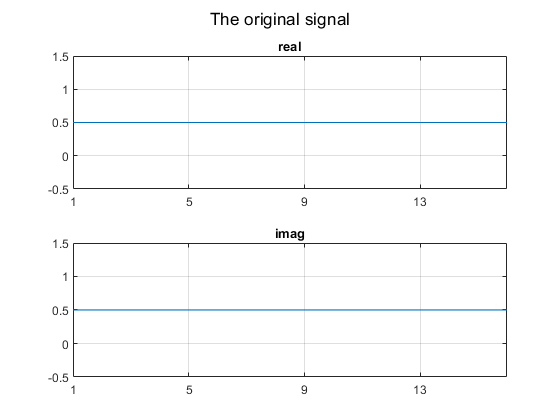

% modulation
s = OTFS_modulation(N,M,x);
plot_s(s, M, N);

% add cp
s_cp = [s(N*M-cp_len+1:N*M);s];

**Case 1: Emanuele Viterbo Channel in time domain**

We pass the signal through the channel first.

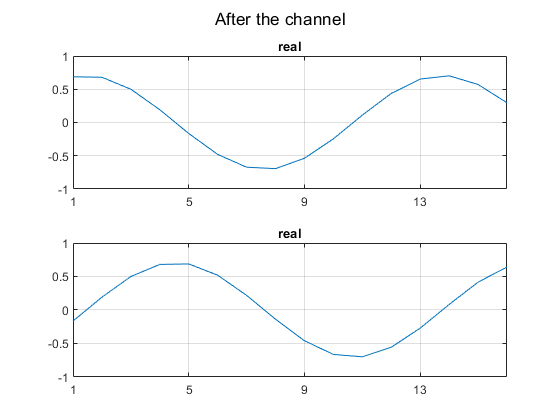

% pass the channel
case1_s_chan = hi*circshift([s_cp.*exp(1j*2*pi/M*(-cp_len:M*N-1)*ki/N).';zeros(cp_len,1)],li);
case1_r = case1_s_chan(cp_len+1:cp_len+(N*M));
plot_r(case1_r, M, N);

% to Rx DD domain
case1_y = OTFS_demodulation(N,M,case1_r);

1st, we need  to generate the channel in the DD domain using perfect CSI

[H, HDD] = OTFS_ddchannel_gen(M, N, 1,li,ki,hi, "real_channel", true);
xDD = x.';
xDD = xDD(:);
yDD = case1_y.';
yDD = yDD(:);
yDD2 = HDD*xDD;
yDD_diff = abs(yDD - yDD2);
fprintf("The yDD difference is %e\n", sum(yDD_diff));

The yDD difference is 3.303351e-15


if sum(yDD_diff > 1e-13) > 0
    error("  - there are element-wise difference.");
else
    disp("  - all elements are equal.");
end

  - all elements are equal.


Then, we estimate the channel in the DD domain

hi_est = zeros(N, 1);
ki_est = zeros(N, 1);
li_est = zeros(N, 1);
for N_id = 1:N
    ch_est_delay = 3;
    ch_est_doppl = N_id;
    ki_est(N_id) = ch_est_doppl - 1;
    li_est(N_id) = ch_est_delay - 1;
    pss_beta = exp(1j*2*pi*(1 - 1)/M*(ch_est_doppl - 1)/N);
    hi_est(N_id) = case1_y(ch_est_doppl, ch_est_delay)/x_value/pss_beta;
end
[~, HDD_est] = OTFS_ddchannel_gen(M, N, N,li_est,ki_est,hi_est);
disp("- Rough estimation");

- Rough estimation


HDD_est_err = abs(HDD_est - HDD);
fprintf("  - The HDD_est error is %e\n", sum(HDD_est_err, "all"));

  - The HDD_est error is 7.325976e+00


yDD_est_diff = abs(HDD_est*xDD - yDD);
fprintf("  - The yDD_est difference is %e\n", sum(yDD_est_diff));

  - The yDD_est difference is 2.590124e+00


If you look at $y$, you will realize that the channe is different when the pilots are different. The reason is that the path difference is $e^{\frac{j2\pi k_i l}{MN}}$ while we use $e^{\frac{j2\pi k' l}{MN}}$ to estimate the channel. Now, we try to use the correct coefficient to cancel it.

hi_est2 = zeros(N, 1);
ki_est2 = ki*ones(N, 1);
li_est2 = zeros(N, 1);
for N_id = 1:N
    ch_est_delay = 3;
    ch_est_doppl = N_id;
    li_est2(N_id) = ch_est_delay - 1;
    pss_beta = exp(1j*2*pi*(1 - 1)/M*ki/N);
    hi_est2(N_id) = case1_y(ch_est_doppl, ch_est_delay)/x_value/pss_beta;
end
[~, HDD_est2] = OTFS_ddchannel_gen(M, N, N,li_est2,ki_est2,hi_est2);
disp("- Accurate estimation (impossible)");

- Accurate estimation (impossible)


HDD_est_err2 = abs(HDD_est2 - HDD);
fprintf("  - The HDD_est error is %e\n", sum(HDD_est_err2, "all"));

  - The HDD_est error is 2.227403e-15


yDD_est_diff2 = abs(HDD_est2*xDD - yDD);
fprintf("  - The yDD_est difference is %e\n", sum(yDD_est_diff2));

  - The yDD_est difference is 3.398759e-15


**Functions**

function plot_s(s, M, N)
    figure("name", "The original signal")
    subplot(2,1,1)
    plot(real(s));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    subplot(2,1,2)
    plot(imag(s));
    title("imag");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    sgtitle("The original signal")
end
function plot_r(r, M, N)
    figure("name", "Time domain")
    subplot(2,1,1)
    plot(real(r));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    subplot(2,1,2)
    plot(imag(r));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    sgtitle("After the channel")
end
